## Динамический хаос

## Фазовые портреты аттракторов:

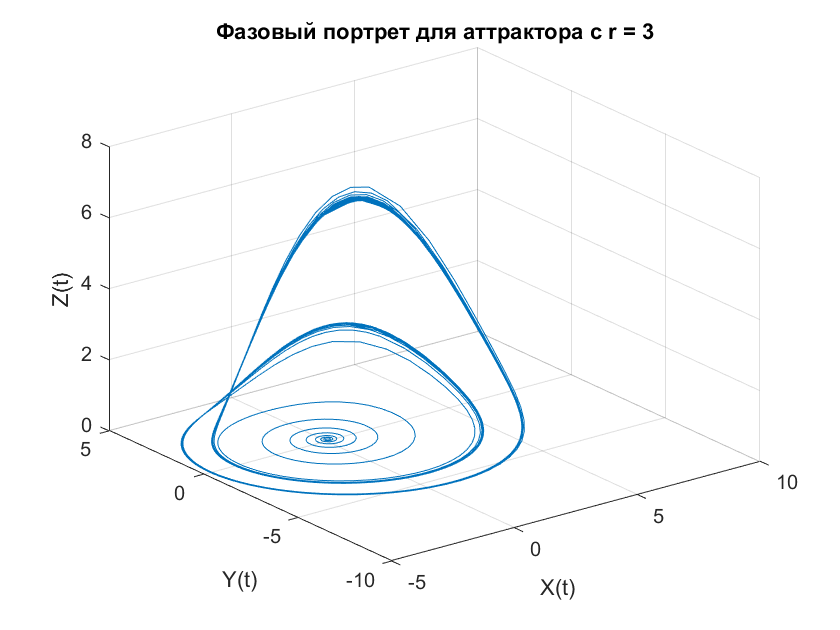

build_attractor(3);

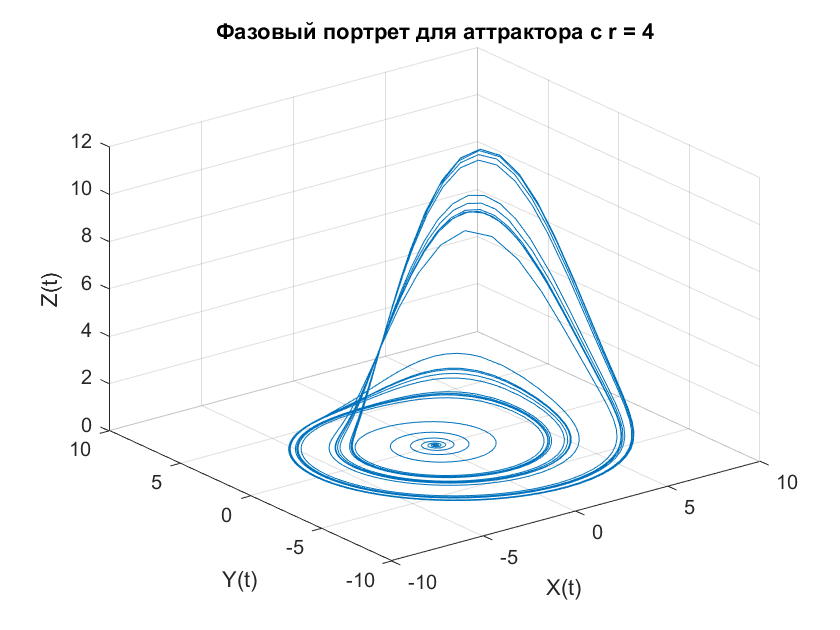

build_attractor(4);

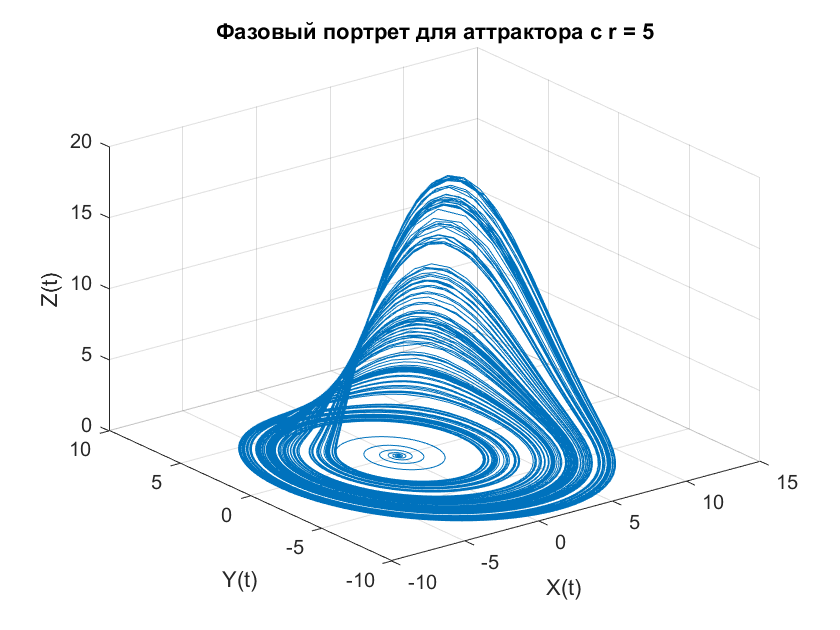

build_attractor(5);

## Бифуркационная диаграмма

%dt = 0.01;
N = 30;

figure;
ax(1) = subplot(1,1,1);
hold on
xlabel ('r');
ylabel ('x');
title("Бифуркационная диаграмма");
grid();

for r=0:0.1:10
    x = zeros(N,1);
    x(1) = 0.1;
    for i=1:N
        if x(i) <= 0.5 && x(i) >= 0
            x(i+1) = r*x(i);
        elseif x(i) > 0.5 && x(i) <= 1
            x(i+1) = -r*(x(i)-1);
        else
            break
        end
    end
    plot(ax(1),r,x,'color','blue','marker','.');
end

## Дополнительные главы линейной алгебры

## Полярное разложение

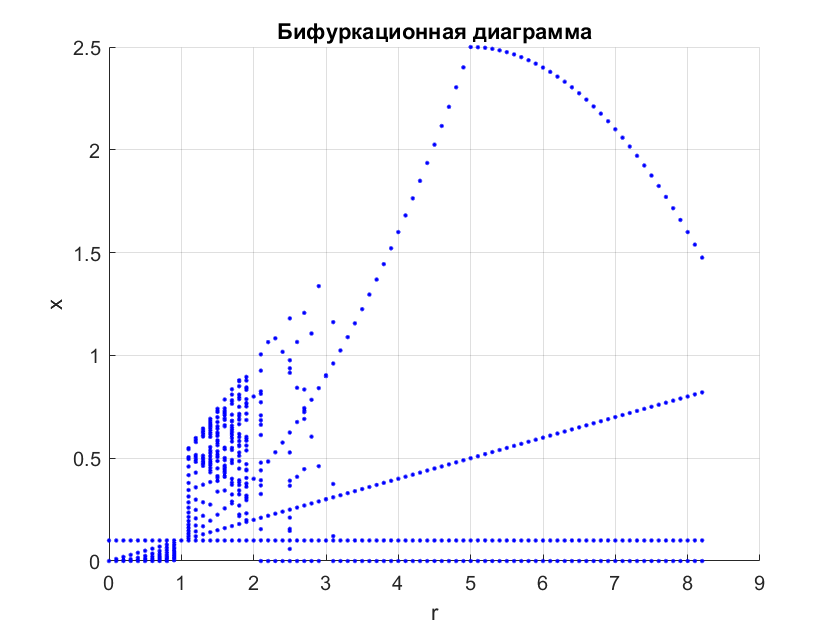

hold off;

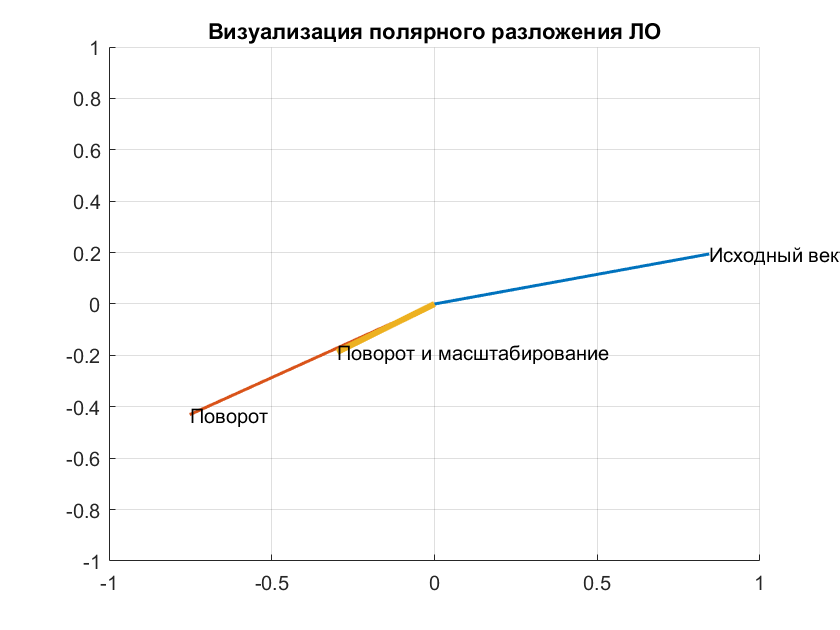

figure;
ax(1) = subplot(1,1,1);
axis([-1 1 -1 1]);
grid();
title("Визуализация полярного разложения ЛО");
A = rand(2, 2) - 0.5;
if det(A) ~=0
    [U,S,V] = svd(A);
    B = U* V';
    C = V*S*V';
    vec = rand(2,1);
    vecB = B*vec;
    vecC = C*vecB;
    hold on;
    plot(ax(1), [0 vec(1)], [0 vec(2)], 'LineWidth', 1.5);
    plot(ax(1), [0 vecB(1)], [0 vecB(2)], 'LineWidth', 1.5);
    plot(ax(1), [0 vecC(1)], [0 vecC(2)], 'LineWidth', 3);
    text(vec(1), vec(2), "Исходный вектор");
    text(vecB(1), vecB(2), "Поворот");
    text(vecC(1), vecC(2), "Поворот и масштабирование");
    hold off;
    
end

## Сингулярное разложение A(x,y,z)=(2x-2y+2z,z-x)

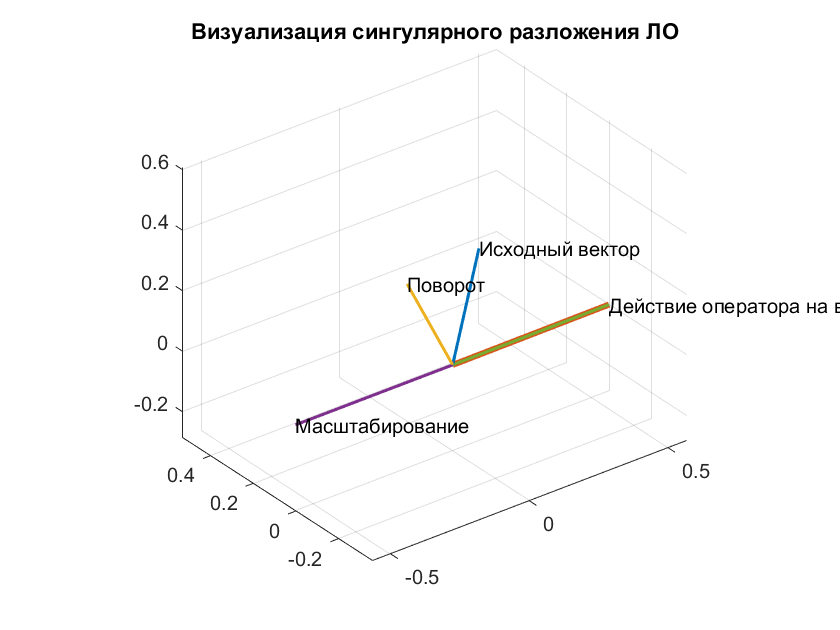

figure;
ax(1) = subplot(1,1,1);
axis equal;
grid();
title("Визуализация сингулярного разложения ЛО");

A = [2 -2 2; -1 0 1];
[U,S,V] = svd(A);
vec = rand(3, 1);
hold on;
view(3);
plot3(ax(1), [0 vec(1)], [0 vec(2)], [0 vec(3)], 'LineWidth', 1.5);
text(vec(1), vec(2), vec(3), "Исходный вектор")
%plot(ax(1), [0 vecy(1)], [0 vecy(2)], 'g', 'LineWidth', 1.5);
veca = A*vec;
%vecay = A*vec;
plot3(ax(1), [0 veca(1)], [0 veca(2)], [0 0], 'LineWidth', 3, 'DisplayName', 'Действие оператора на вектор');
text(veca(1), veca(2), "Действие оператора на вектор")
%plot3(ax(1), [0 vecay(1)], [0 vecay(2)], [0 0], 'b', 'LineWidth', 1.5);
vecV = V.' * vec;
plot3(ax(1), [0 vecV(1)], [0 vecV(2)], [0 vecV(3)], 'LineWidth', 1.5, 'DisplayName', 'Изометрия');
text(ax(1), vecV(1), vecV(2), vecV(3), "Поворот");
vecS = S * vecV;
plot3(ax(1), [0 vecS(1)], [0 vecS(2)], [0 0], 'LineWidth', 1.5, 'DisplayName', 'Поворот вектора');
text(ax(1), vecS(1), vecS(2), "Масштабирование");
vecU = U * vecS;
plot3(ax(1), [0 vecU(1)], [0 vecU(2)], [0 0], 'LineWidth', 1.5, 'DisplayName', 'Поворот вектора');
%legend();
hold off;

## Построение псевдообратной матрицы с помощью скелетного разложения

A = [1 2 3 4; 2 4 6 8]

A =      1     2     3     4
     2     4     6     8


pseudoinverse(A)

Псевдообратная матрица к А:


PA =     0.0067    0.0133
    0.0133    0.0267
    0.0200    0.0400
    0.0267    0.0533


Псевдообратная матрица к А с помощью функции pinv:


truePA =     0.0067    0.0133
    0.0133    0.0267
    0.0200    0.0400
    0.0267    0.0533



A = [1 0 2 1; 0 1 2 1; 0 2 4 2]

A =      1     0     2     1
     0     1     2     1
     0     2     4     2


pseudoinverse(A)

Псевдообратная матрица к А:


PA =     0.5455   -0.0909   -0.1818
   -0.4545    0.1091    0.2182
    0.1818    0.0364    0.0727
    0.0909    0.0182    0.0364


Псевдообратная матрица к А с помощью функции pinv:


truePA =     0.5455   -0.0909   -0.1818
   -0.4545    0.1091    0.2182
    0.1818    0.0364    0.0727
    0.0909    0.0182    0.0364


function [] = build_attractor(r)
    [t, X] = ode45(@equation, [-500 500], [0; 0; 0]);
    plot3(X(:,1), X(:,2), X(:,3));
    xlabel("X(t)");
    ylabel("Y(t)");
    zlabel("Z(t)");
    title("Фазовый портрет для аттрактора с r = " + string(r));
    grid();
    function dXdt = equation(t, X)
    a = 0.2;
    b = 0.2;
    dx1 = -X(2) - X(3);
    dx2 = X(1) + a*X(2);
    dx3 = b + (X(1)-r)*X(3);
    
    dXdt = [dx1; dx2; dx3];
    end
end

function [] = pseudoinverse(A)
    C = rref(A);
    C( ~any(C,2), : ) = [];
    PC = C.' * inv(C * C.');
    B = A * PC;
    PB = inv(B.' * B) * B.';
    fprintf("Псевдообратная матрица к А:\n")
    PA = PC * PB
    fprintf("Псевдообратная матрица к А с помощью функции pinv:\n")
    truePA = pinv(A)
end
